PHYSICS 434 

LAB 6 

AVI SOVAL; THOMAS CONAWAY, JEFF JIANG

11.14.19 

PROBLEM 1 

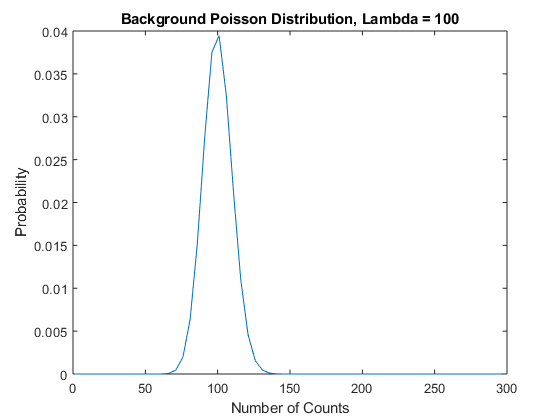

background = makedist('Poisson','lambda',100); 
x = 1:5:300; 
bg = pdf(background,x); 

figure(1)
plot(x,bg); 
xlabel('Number of Counts'); 
ylabel('Probability'); 
title('Background Poisson Distribution, Lambda = 100'); 

thresh = 3.5e-6; 
y = icdf(background,1-thresh); 
disp("The sigma value is " + y)

The sigma value is 148


PROBLEM 2 

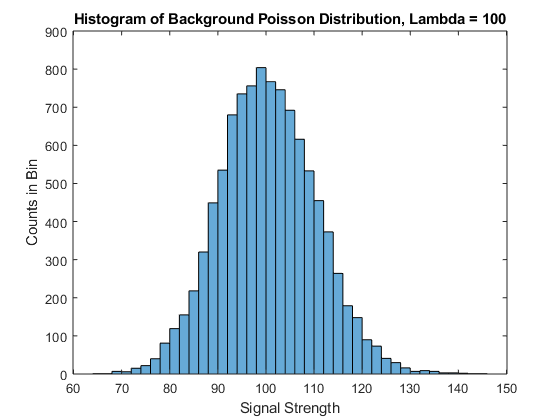

data = poissrnd(100,[10000 1]); 

figure(2)
histogram(data); 
xlabel('Signal Strength'); 
ylabel('Counts in Bin'); 
title('Histogram of Background Poisson Distribution, Lambda = 100'); 

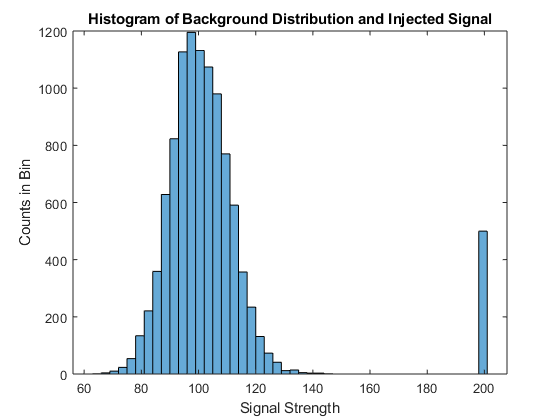


signal_strength = 200; 
signal_count = 500;

signal_data = zeros(1,length(data) + signal_count); 
signal_data(1:length(data)) = data; 
signal_data(length(data)+1:end) = signal_strength; 

all_data = signal_data; 

figure(3)
histogram(all_data); 
xlabel('Signal Strength'); 
ylabel('Counts in Bin'); 
title('Histogram of Background Distribution and Injected Signal'); 

PROBLEM 3 

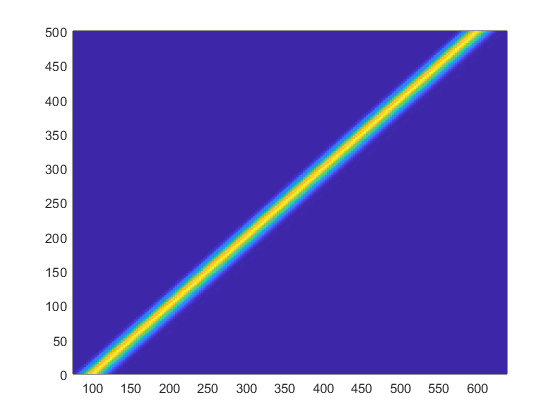

signal_strengths = linspace(0,500,10000); 
injected_data = zeros(10000); 
all_injected_data = injected_data;
num_signals = 500; 
ix = randi(10000,500,1); 

for i = 1:10000
    
    all_injected_data(i,:) = data;  
    all_injected_data(i,ix) = data(ix) + signal_strengths(i);
    injected_data(i,ix) = data(ix) + signal_strengths(i); 

end

figure(4)
injected_data(injected_data==0) = nan; 
[scratch, signal] = meshgrid(signal_strengths); 
histogram2(injected_data,signal,200,'DisplayStyle','tile','ShowEmptyBins','on'); 


% signals = randi(500,500,1); 
% ix = randi(10000,500,1); 
% injected_data = data; 
% 
% for i = 1:length(ix) 
%     
%     injected_data(ix(i)) = injected_data(ix(i)) + signals(i); 
%     
% end
% 
% strength = linspace(0,500,10000); 
% [scratch, signal] = meshgrid(strength); 
% 
% histogram2(injected_data,signal(:,1),100,'DisplayStyle','tile','ShowEmptyBins','on'); 

% 3b, injected signal power of 200 

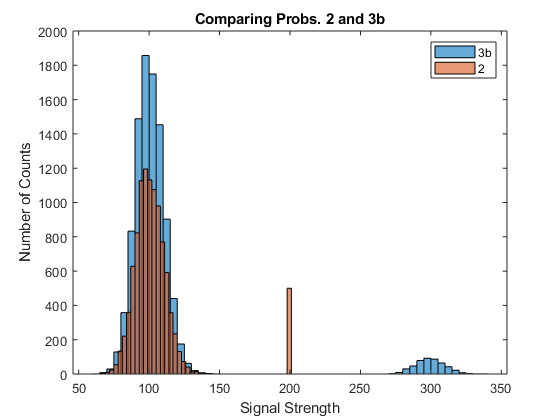

figure(5)
histogram(all_injected_data(4000,:))
hold on 
histogram(all_data); 
xlabel('Signal Strength'); 
ylabel('Number of Counts'); 
title('Comparing Probs. 2 and 3b') 
legend('3b','2'); 


% have to check and fix it here, I think i am making a small error
% somewhere in my for loop 